# Assemblage de n pièces

On crée un assemblage L de n pièces uniformes sur [8,12]. 


$$L = X_1 + ... + X_n \underset{n\rightarrow +\infty}{\sim} \mathcal{N}(n\times10, n\times \frac{(12-8)^2}{12})$$


On obtient la loi de L par simulation.

On commence par un assemblage de 2 pièces. 

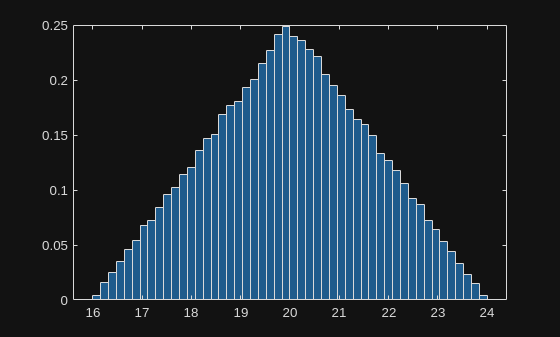

Nsimu=100000;
n=2;
L2 = zeros(Nsimu,1);
for i=1:n
    L2 = L2 + unifrnd(8,12,Nsimu,1);
end
histogram(L2,50,'normalization','pdf')

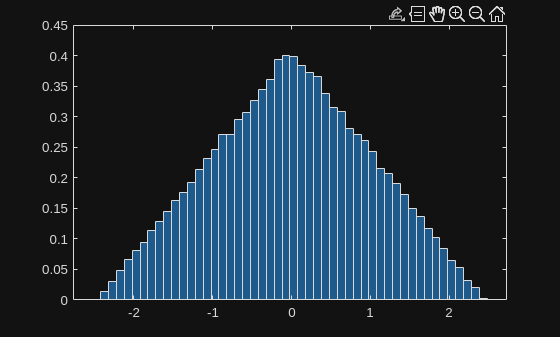

histogram((L2-n*10)/(2/sqrt(3)*sqrt(n)),50,'normalization','pdf')

On simule maintenant un assemblage de 5 pièces. 

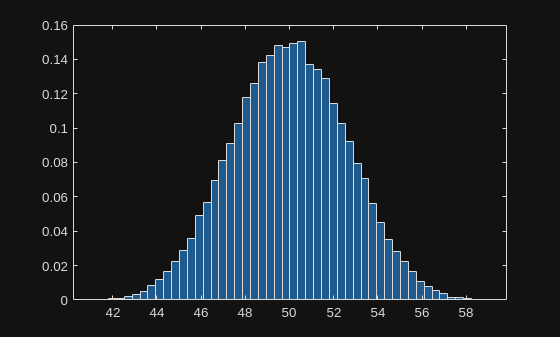

Nsimu=100000;
n=5;
L5 = zeros(Nsimu,1);
for i=1:n
    L5 = L5 + unifrnd(8,12,Nsimu,1);
end
histogram(L5,50,'normalization','pdf')

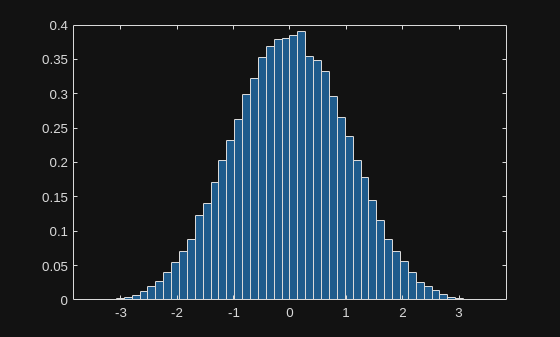

histogram((L5-n*10)/(2/sqrt(3)*sqrt(n)),50,'normalization','pdf')

Puis un assemblage de 100 pièces.

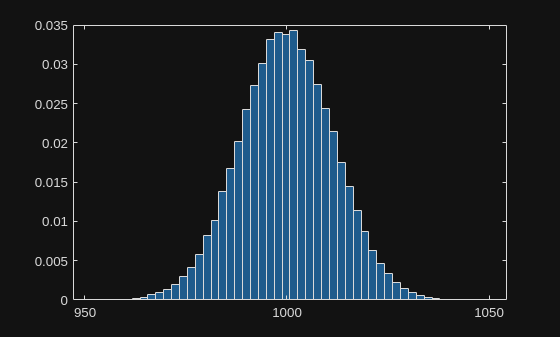

Nsimu=100000;
n=100;
L100 = zeros(Nsimu,1);
for i=1:n
    L100 = L100 + unifrnd(8,12,Nsimu,1);
end
histogram(L100,50,'normalization','pdf')

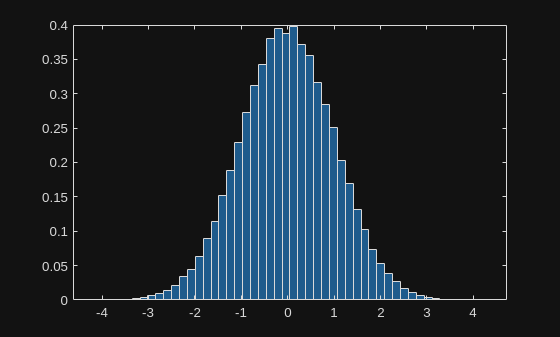

histogram((L100-n*10)/(2/sqrt(3)*sqrt(n)),50,'normalization','pdf')

On compare visuellement les histogrammes obtenus : 

subplot(1,3,1); histogram(L2,50,'normalization','pdf');
subplot(1,3,2); histogram(L5,50,'normalization','pdf');
subplot(1,3,3); histogram(L100,50,'normalization','pdf');


Pour que les discributions soient comparables on centre et on réduit les variables aléatoires. Elles sont maintenant toutes d'espérance 0 et de variance 1. 

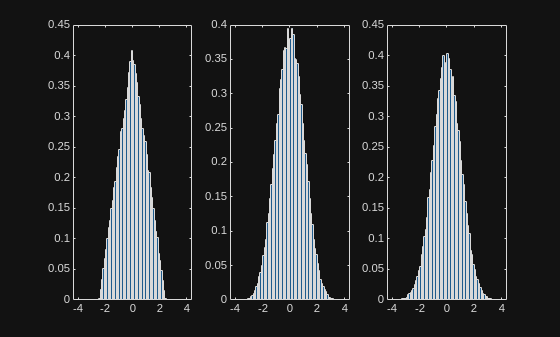

subplot(1,3,1); histogram((L2-2*10)/(2/sqrt(3)*sqrt(2)),-4:0.1:4,'normalization','pdf');
subplot(1,3,2); histogram((L5-5*10)/(2/sqrt(3)*sqrt(5)),-4:0.1:4,'normalization','pdf');
subplot(1,3,3); histogram((L100-100*10)/(2/sqrt(3)*sqrt(100)),-4:0.1:4,'normalization','pdf')

On se fise n = 100 et on calcule maintenant la probabilité $P(|L - 1000| >30)$ par Monte Carlo ainsi qu'un intervalle de confiance.

phat = sum(abs(L100-1000)>30)/Nsimu

phat = 0.0092


borneinf=phat-1.96*sqrt(phat*(1-phat))/sqrt(Nsimu)

borneinf = 0.0086

bornesup=phat+1.96*sqrt(phat*(1-phat))/sqrt(Nsimu)

bornesup = 0.0098